# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

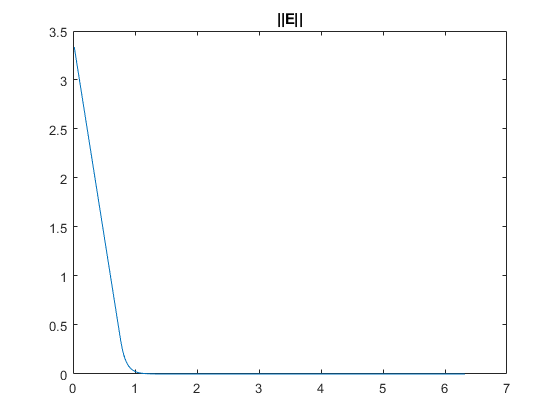

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k m;

down_sample_amount = 1;

% Circle
D = .8; k = 10; m = .4;h = 0.02; % m > 1
position = importdata("circle.mat");


l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
      
state(:,1) =[position(1,1)+2.5; position(2,1)+.5; 0];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;

for t =1 : T
    n1 = 0*randn(1);
    n2 = 0*randn(1);
    % x= current state
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w,n1,n2);
    
     linear_vel(t) = v+n1;
     angular_vel(t) = w+n2;
     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [(v+n1)*cos(state(3,t)); (v+n1)*sin(state(3,t)); w+n2];
    
end
E = position-[xb;yb];
for i = 1:length(position)
    E_norm(i) = norm(E(:,i));
end

% save("circle_high_Error_2","state")
figure
plot([1:length(position)]*h,E_norm)
title('||E||')

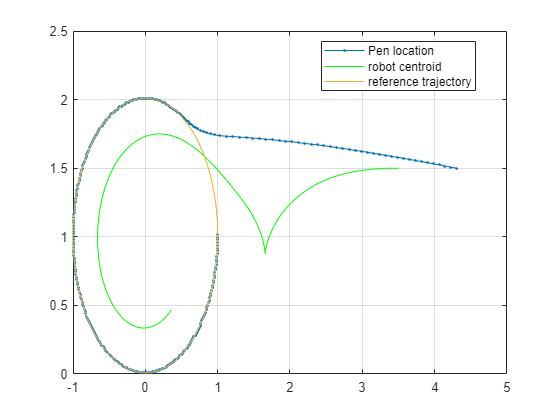


figure
plot(xb, yb, '.-')
hold on;
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:));
grid on;
legend('Pen location', 'robot centroid', 'reference trajectory', "location", 'best')
hold off

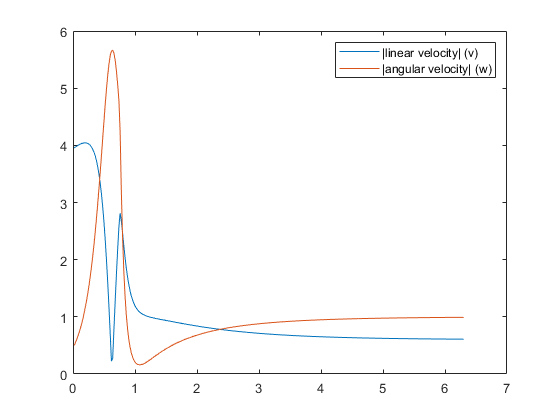


figure
plot([1:size(linear_vel,2)]*h, abs(linear_vel)); hold on
plot([1:size(angular_vel,2)]*h, abs(angular_vel));
legend('|linear velocity| (v)', '|angular velocity| (w)')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k m
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

if norm(E) > m
        v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
    else
    v_feedback = [xVelocity; yVelocity] - k*E;
end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end